# Flux Balance Analysis

## Author(s): Ronan M.T. Fleming, Leiden University

## Reviewer(s):

## INTRODUCTION

In this tutorial, Flux Balance Analysis (FBA) is introduced using the Lactococcus lactis core model, with functions in the COBRA Toolbox v3.0 [2].  

Flux balance analysis is a solution to the optimisation problem


$$
\begin{array}{ll}
\textrm{max} & c^{T}v\\
\text{s.t.} & Sv=b\\
 & l\leq v\leq u
\end{array}
\end{equation}$$


where $c$ is a vector of linear objective coefficients, $S$ is an m times n matrix of stoichiometric coefficients for m molecular species involved in n reactions. $l\;\mathrm{and}\;u\;$are n times 1 vectors that are the lower and upper bounds on the n times 1 variable vector $v\;$of reaction rates (fluxes). The optimal objective value is $c^{T}v^{\star}$  is always unique, but the optimal vector $v^{\star}$ is usually not unique.

In summary, the data is {c,S,l,u} and the variable being optimised is v.

## TIMING

*< 1 hrs*

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

## PROCEDURE

changeCobraSolver('glpk')

 > The solver compatibility is not tested with MATLAB R2018b.


ans = logical
   1


model = readSBML('llactis.seqplus.xml',1000)

model = struct with fields:
    modelAnnotation: '<annotation>↵  <listOfKeyValueData xmlns="http://pysces.sourceforge.net/KeyValueData">↵    <data id="genbank_structured_comment" value="OrderedDict([('Genome-Annotation-Data', OrderedDict([('Annotation Provider', 'NCBI'), ('Annotation Date', '01/10/2018 19:18:58'), ('Annotation Pipeline', 'NCBI Prokaryotic Genome'), ('Annotation Method', 'Best-placed reference protein'), ('Annotation Software revision', '4.4'), ('Features Annotated', 'Gene; CDS; rRNA; tRNA; ncRNA;'), ('Genes (total)', '2,594'), ('CDS (total)', '2,508'), ('Genes (coding)', '2,339'), ('CDS (coding)', '2,339'), ('Genes (RNA)', '86'), ('rRNAs', '7, 6, 6 (5S, 16S, 23S)'), ('complete rRNAs', '7, 6, 6 (5S, 16S, 23S)&

modmodel=model

modmodel = struct with fields:
    modelAnnotation: '<annotation>↵  <listOfKeyValueData xmlns="http://pysces.sourceforge.net/KeyValueData">↵    <data id="genbank_structured_comment" value="OrderedDict([('Genome-Annotation-Data', OrderedDict([('Annotation Provider', 'NCBI'), ('Annotation Date', '01/10/2018 19:18:58'), ('Annotation Pipeline', 'NCBI Prokaryotic Genome'), ('Annotation Method', 'Best-placed reference protein'), ('Annotation Software revision', '4.4'), ('Features Annotated', 'Gene; CDS; rRNA; tRNA; ncRNA;'), ('Genes (total)', '2,594'), ('CDS (total)', '2,508'), ('Genes (coding)', '2,339'), ('CDS (coding)', '2,339'), ('Genes (RNA)', '86'), ('rRNAs', '7, 6, 6 (5S, 16S, 23S)'), ('complete rRNAs', '7, 6, 6 (5S, 16S, 23

## Load L.lactis core model

The most appropriate way to load a model into The COBRA Toolbox is to use the `readCbModel` function. 


% you can also use this method
% fileName = 'llactis_core_model';
% if ~exist('modelOri','var')
%     modelOri = readCbModel(fileName);
% end
% %backward compatibility with primer requires relaxation of upper bound on
% %ATPM
% modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
% model = modelOri;


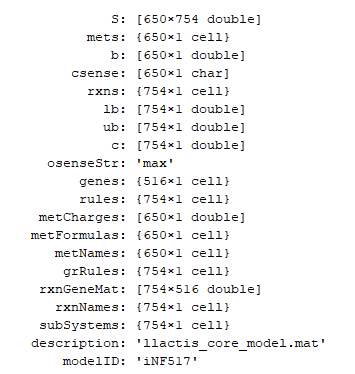

The meaning of each field in a standard model is defined in the [standard COBRA model field definition](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/notes/COBRAModelFields.md).

In general, the following fields should always be present: 

- **S**, the stoichiometric matrix

- **mets**, the identifiers of the metabolites

- **b**, Accumulation (positive) or depletion (negative) of the corresponding metabolites. 0 Indicates no concentration change.

- **csense**, indicator whether the b vector is a lower bound ('G'), upper bound ('L'), or hard constraint 'E' for the metabolites.

- **rxns**, the identifiers of the reactions

- **lb**, the lower bounds of the reactions

- **ub**, the upper bounds of the reactions

- **c**, the linear objective

- **genes**, the list of genes in your model 

- **rules**, the Gene-protein-reaction rules in a computer readable format present in your model.

- **osenseStr**, the objective sense either `'max'` for maximisation or `'min'` for minimisation

## Checking the non-trivial constraints on a model

#### What are the default constraints on the model? 

#### Hint: `printConstraints`

printConstraints(model,-1000,1000)

MinConstraints:
EX_nh4_e	-0.59
EX_pnto__R_e	-0.00062
EX_ribflv_e	-0.00036
EX_ins_e	-0.00255
EX_his__L_e	-0.01
EX_ade_e	-0.01014
EX_gly_e	-0.04
EX_lys__L_e	-0.04
EX_ura_e	-0.01222
EX_glc__D_e	-2.12
EX_phe__L_e	-0.02
EX_xan_e	-0.00901
EX_nac_e	-0.00111
EX_ser__L_e	-0.11
EX_ile__L_e	-0.05
EX_lac__L_e	0.4
EX_ac_e	0.83
EX_leu__L_e	-0.06
EX_arg__L_e	-0.02
EX_thm_e	-0.00041
EX_for_e	1.71
EX_glu__L_e	-0.05
EX_orot_e	-0.00439
EX_ala__L_e	-0.04
EX_thymd_e	-0.00283
EX_etoh_e	0.44
EX_pro__L_e	0.03
EX_4abz_e	-0.00999
EX_asp__L_e	-0.01
EX_thr__L_e	-0.06
EX_met__L_e	-0.01
EX_val__L_e	-0.05
EX_gua_e	-0.00906
EX_cys__L_e	-0.02
maxConstraints:
EX_nh4_e	0.44
EX_glc__D_e	-0.92
EX_phe__L_e	0.01
EX_ser__L_e	-0.04
EX_ile__L_e	-0.01
EX_lac__L_e	0.92
EX_ac_e	1.92
EX_leu__L_e	-0.01
EX_arg__L_e	-0.01
EX_tyr__L_e	0.01
EX_for_e	3.94
EX_glu__L_e	-0.01
EX_etoh_e	1.02
EX_pro__L_e	0.44
EX_asp__L_e	0.05
EX_thr__L_e	-0.02
EX_val__L_e	-0.01
EX_orn__L_e	0.01


## Example 1: Calculating growth rates

Growth of S.cerevisiae on glucose can be simulated under aerobic conditions.  

#### What is the growth rate of L.lactis on glucose (uptake rate = 18.5 mmol/gDW/h) under aerobic and anaerobic conditions?  

#### Hint: `changeRxnBounds`, `changeObjective`, `optimizeCbModel`, `printFluxVector`

To set the maximum glucose uptake rate to 18.5 mmol gDW-1 hr-1 (millimoles per gram dry cell weight per hour, the default flux units used in the COBRA Toolbox), enter:

model = changeRxnBounds(model,'EX_glc__D_e',-18.5,'l');

This changes the lower bound ('l') of the glucose exchange reaction to -18.5, a biologically realistic uptake rate.  By convention, exchange reactions are written as export reactions (e.g. ‘glc[e] <==>’), so import of a metabolite is a negative flux.  

To allow unlimited oxygen uptake, enter:

model = changeRxnBounds(model,'EX_o2_e',-1000,'l');

By setting the lower bound of the oxygen uptake reaction to such a large number, it is practically unbounded. 

The default behaviour of the function `optimizeCbModel` is to conduct flux balance analysis on a `model` structure.  This function is the most powerful function in the COBRA toolbox and has many optional inputs and outputs but for a straightforward flux balance analysis, the following fields of a model are the required input:

%    model:             (the following fields are required - others can be supplied)
%
%                         * S  - `m x 1` Stoichiometric matrix
%                         * c  - `n x 1` Linear objective coefficients
%                         * lb - `n x 1` Lower bounds
%                         * ub - `n x 1` Upper bounds

To perform FBA with maximization of the biomass reaction as the objective, enter:

FBAsolution = optimizeCbModel(model,'max')

FBAsolution = struct with fields:
    origStatText: []
               f: 0.0426
               v: [740×1 double]
               y: [649×1 double]
               w: [740×1 double]
               s: [649×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0260
           basis: []
          vars_v: []
               x: [740×1 double]


#### What are the main fields to check in the FBAsolution structure?

#### Hint: `help optimizeCbModel`

There are many outputs fields in the `FBAsolution` structure, but the key ones for any FBA solution are

%    solution:       solution object:
%             * f - Objective value
%             * v - Reaction rates (Optimal primal variable, legacy FBAsolution.x)
%             * stat - Solver status in standardized form

FBAsolution.f  gives the value of the objective function, which should be 0.0426 mmol gDW-1 hr-1 

FBAsolution.f

ans = 0.0426

This is the same as 

model.c'*FBAsolution.v

ans = 0.0426

This means that the model predicts a growth rate of 0.0426 hr-1.  Inspection of the flux distribution vector FBAsolution.v shows that there is high flux in the glycolysis, pentose phosphate, TCA cycle, and oxidative phosphorylation pathways, and that no organic by-products are secreted (Figure 2a).

`FBAsolution.v` gives the optimal flux vector

FBAsolution.v

ans = 	1.0e+03 *

         0
    0.0000
         0
         0
    0.0000
    0.0185
         0
    0.0000
    0.0000
   -1.0000


Inspection of the flux distribution is more convenient with the `printFluxVector` function

fluxData = FBAsolution.v;
nonZeroFlag = 1;
printFluxVector(model, fluxData, nonZeroFlag)

3MOPDC              	    0.005373
CTPS1               	    0.004383
GLCpts              	        18.5
PRPPS               	     0.01099
FOLt                	   4.264e-07
TRPTA               	       -1000
CPSS_LLA            	   0.0002729
UAAGLS1_1           	    0.005074
3OAR140             	    0.005193
NH3c                	     0.05018
PSCVT               	    0.006806
EX_nh4_e            	       0.136
RHCYS               	   0.0006751
PMEVK               	    9.38e-05
DHQTi               	    0.006806
EX_acald_e          	       2.046
EX_pnto__R_e        	  -8.527e-06
3HAD40              	    0.005193
NNATr               	   8.527e-05
EAR100x             	    0.005193
DIACTt              	      0.1174
SHK3Dr              	    0.006806
SERD_L              	       0.098
DASYN_LLA           	     0.01172
THRTRS_1            	     0.01182
ATPM                	       34.81
ILETRS_1            	     0.01039
EX_ins_e            	    -0.00255
3HAD100             	    0.005193
ORNTAC_1      

#### What does FBAsolution.stat mean?

[Answer Link](https://groups.google.com/forum/#!topic/cobra-toolbox/3D_INvKYoGc)

FBAsolution.stat is either 1,2,0 or -1, and is a translation from FBAsolution.origStat, which is returned by each solver in a solver specific way. That is, not all solvers return the same type of FBAsolution.origStat and because the cobra toolbox can use many solvers, we need to return to the user of optimizeCbModel.m a standard representation, which is what FBAsolution.stat is.

When running optimizeCbModel.m, unless FBAsolution.stat = 1, then no solution is returned. This means that it is up to the person calling optimizeCbModel to adapt their code to the case when no solution is returned, by checking the value of FBAsolution.stat first.

FBAsolution.stat

ans = 1

                                                                        
$$\matrix{
\text{Stat}    	& Status 	   \cr
1			& Optimal \cr
2			& Unbounded\cr
0			& Infeasible\cr
-1			& No Solution\cr
}$$


## Example 3:  Anerobic growth

Growth of L.lactis on glucose can be simulated under anaerobic conditions.  

#### What is the optimal growth rate under anaerobic conditions?

[Respiration Capacity of the Fermenting Bacterium Lactococcus lactis and Its Positive Effects on Growth and Survival ](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC95345/)

*"Oxygen is a major determinant of both survival and mortality of aerobic organisms. For the facultative anaerobe Lactococcus lactis, oxygen has negative effects on both growth and survival."*

#### Hint: changeRxnBounds

Next, the same simulation is performed under anaerobic conditions.  With the same model:

model = changeRxnBounds(model,'EX_o2_e',0,'l');
printConstraints(model,-1000,1000)

MinConstraints:
EX_nh4_e	-0.59
EX_pnto__R_e	-0.00062
EX_ribflv_e	-0.00036
EX_ins_e	-0.00255
EX_his__L_e	-0.01
EX_ade_e	-0.01014
EX_gly_e	-0.04
EX_lys__L_e	-0.04
EX_ura_e	-0.01222
EX_glc__D_e	-18.5
EX_phe__L_e	-0.02
EX_xan_e	-0.00901
EX_nac_e	-0.00111
EX_ser__L_e	-0.11
EX_ile__L_e	-0.05
EX_lac__L_e	0.4
EX_ac_e	0.83
EX_leu__L_e	-0.06
EX_arg__L_e	-0.02
EX_thm_e	-0.00041
EX_for_e	1.71
EX_glu__L_e	-0.05
EX_orot_e	-0.00439
EX_ala__L_e	-0.04
EX_thymd_e	-0.00283
EX_etoh_e	0.44
EX_pro__L_e	0.03
EX_4abz_e	-0.00999
EX_asp__L_e	-0.01
EX_thr__L_e	-0.06
EX_met__L_e	-0.01
EX_val__L_e	-0.05
EX_gua_e	-0.00906
EX_cys__L_e	-0.02
maxConstraints:
EX_nh4_e	0.44
EX_glc__D_e	-0.92
EX_phe__L_e	0.01
EX_ser__L_e	-0.04
EX_ile__L_e	-0.01
EX_lac__L_e	0.92
EX_ac_e	1.92
EX_leu__L_e	-0.01
EX_arg__L_e	-0.01
EX_tyr__L_e	0.01
EX_for_e	3.94
EX_glu__L_e	-0.01
EX_etoh_e	1.02
EX_pro__L_e	0.44
EX_asp__L_e	0.05
EX_thr__L_e	-0.02
EX_val__L_e	-0.01
EX_orn__L_e	0.01


The lower bound of the oxygen exchange reaction is now 0, so oxygen may not enter the system.  When optimizeCbModel is used as before, the resulting growth rate is now much lower, 0.0426 hr-1.  

FBAsolution2 = optimizeCbModel(model,'max');
FBAsolution2.f

ans = 0.0426

#### What reactions of oxidative phosphorylation are active in anaerobic conditions?

#### Hint: `printFluxVector` `drawFlux`

The flux distribution shows that oxidative phosphorylation is not used in these conditions, and that acetate, formate, and ethanol are produced by fermentation pathways (Figure 2b). Inspection of both flux vectors for comparison:

fluxData = [FBAsolution.v,FBAsolution2.v];
nonZeroFlag = 1;
excFlag = 1;
printFluxVector(model, fluxData, nonZeroFlag, excFlag)

EX_nh4_e            	       0.136       0.136
EX_acald_e          	       2.046       2.046
EX_pnto__R_e        	  -8.527e-06  -8.527e-06
EX_ins_e            	    -0.00255    -0.00255
EX_his__L_e         	   -0.003224   -0.003224
EX_ade_e            	   -0.007257   -0.007257
EX_lys__L_e         	    -0.01516    -0.01516
EX_h2o_e            	       15.77       15.77
EX_ura_e            	   -0.006459   -0.006459
EX_glc__D_e         	       -18.5       -18.5
EX_phe__L_e         	   -0.007164   -0.007164
EX_nac_e            	  -8.527e-05  -8.527e-05
EX_2mbald_e         	    0.005373    0.005373
EX_ser__L_e         	       -0.11       -0.11
EX_diact_e          	      0.1174      0.1174
EX_ile__L_e         	    -0.01576    -0.01576
EX_lac__L_e         	         0.4         0.4
EX_ac_e             	        0.83        0.83
EX_leu__L_e         	    -0.01576    -0.01576
EX_arg__L_e         	       -0.02       -0.02
EX_pi_e             	    -0.02939    -0.02939
EX_for_e            	        3.94 

. 

## Example 4:  Growth on alternate substrates

Just as FBA was used to calculate growth rates of L.lactis on glucose, it can also be used to simulate growth on other substrates.  The core E. coli model contains exchange reactions for 13 different organic compounds, each of which can be used as the sole carbon source under aerobic conditions. 

#### What is the growth rate of L.lactis on succinate?

#### Hint: `changeRxnBounds`

Before trying out new boundary conditions on a model, make sure one's starting point is appropriate.

modmodel

modmodel = struct with fields:
    modelAnnotation: '<annotation>↵  <listOfKeyValueData xmlns="http://pysces.sourceforge.net/KeyValueData">↵    <data id="genbank_structured_comment" value="OrderedDict([('Genome-Annotation-Data', OrderedDict([('Annotation Provider', 'NCBI'), ('Annotation Date', '01/10/2018 19:18:58'), ('Annotation Pipeline', 'NCBI Prokaryotic Genome'), ('Annotation Method', 'Best-placed reference protein'), ('Annotation Software revision', '4.4'), ('Features Annotated', 'Gene; CDS; rRNA; tRNA; ncRNA;'), ('Genes (total)', '2,594'), ('CDS (total)', '2,508'), ('Genes (coding)', '2,339'), ('CDS (coding)', '2,339'), ('Genes (RNA)', '86'), ('rRNAs', '7, 6, 6 (5S, 16S, 23S)'), ('complete rRNAs', '7, 6, 6 (5S, 16S, 23

model = modmodel

model = struct with fields:
    modelAnnotation: '<annotation>↵  <listOfKeyValueData xmlns="http://pysces.sourceforge.net/KeyValueData">↵    <data id="genbank_structured_comment" value="OrderedDict([('Genome-Annotation-Data', OrderedDict([('Annotation Provider', 'NCBI'), ('Annotation Date', '01/10/2018 19:18:58'), ('Annotation Pipeline', 'NCBI Prokaryotic Genome'), ('Annotation Method', 'Best-placed reference protein'), ('Annotation Software revision', '4.4'), ('Features Annotated', 'Gene; CDS; rRNA; tRNA; ncRNA;'), ('Genes (total)', '2,594'), ('CDS (total)', '2,508'), ('Genes (coding)', '2,339'), ('CDS (coding)', '2,339'), ('Genes (RNA)', '86'), ('rRNAs', '7, 6, 6 (5S, 16S, 23S)'), ('complete rRNAs', '7, 6, 6 (5S, 16S, 23S)&

For example, to simulate growth on succinate instead of glucose, first use the changeRxnBounds function to set the lower bound of the glucose exchange reaction (EX_glc(e)) to 0.  

model = changeRxnBounds(model,'EX_glc__D_e',0,'l');

Then use changeRxnBounds to set the lower bound of the succinate exchange reaction (EX_succ(e)) to -20 mmol gDW-1 hr-1 (an arbitrary uptake rate).  

model = changeRxnBounds(model,'EX_succ_e',-20,'l');

As in the glucose examples, make sure that the biomass reaction is set as the objective (the function checkObjective can be used to identify the objective reaction(s)), 

checkObjective(model);

summaryT = 21×5 table
    Coefficient       Metabolite       metID     Reaction      RxnID
    ___________    ________________    _____    ___________    _____

       -0.0064     CPS_LLA[c]           113     BIOMASS_LLA     739 
      -0.00074     DNA_LLA[c]           114     BIOMASS_LLA     739 
      -0.00015     LTAAlaGal_LLA[c]     115     BIOMASS_LLA     739 
        -0.119     PG[c]                119     BIOMASS_LLA     739 
     -0.004201     PROT_LLA_v3[c]       121     BIOMASS_LLA     739 
      -0.00329     RNA_LLA[c]           122     BIOMASS_LLA     739 
          39.4     adp[c]               155     BIOMASS_LLA     739 
         -39.4     atp[c]               190     BIOMASS_LLA     739 
     -0.000138     clpn_LLA[c]          214     BIOMASS_LLA     739 
       -0.0002     coa[c]               218     

Use optimizeCbModel to perform FBA, then the growth rate, given by FBAsolution.f, will be Not available  

FBAsolution = optimizeCbModel(model,'max');
FBAsolution.f

ans = NaN

Growth can also be simulated under anaerobic conditions with any substrate by using changeRxnBounds to set the lower bound of the oxygen exchange reaction (EX_o2(e)) to 0 mmol gDW-1 hr-1, so no oxygen can enter the system.  When this constraint is applied and succinate is the only organic substrate, optimizeCbModel returns a growth rate is not available

model = changeRxnBounds(model,'EX_o2_e',0,'l');
FBAsolution = optimizeCbModel(model,'max');
FBAsolution.f

ans = NaN

In this case, FBA predicts that growth is not possible on succinate under anaerobic conditions.  Because the maximum amount of ATP that can be produced from this amount of succinate is less than the minimum bound of 8.39 mmol gDW-1 hr 1 of the ATP maintenance reaction, ATPM, there is no feasible solution.

## TROUBLESHOOTING

Although it does not happen often, there are many reasons why an FBA problem might not solve, so they are divided into three categories. 

%      solution.stat - Solver status in standardized form:
%                      * `-1` - No solution reported (timelimit, numerical problem etc)
%                      * `1` - Optimal solution
%                      * `2` - Unbounded solution
%                      * `0` - Infeasible

`solution.stat == 0`  means that the problem is overconstrainted and no feasible flux vector v exists. The constraints need to be relaxed before the problem will solve. See tutorial_relaxedFBA.mlx

`solution.stat = 2`  means that the problem is underconstrained to the extent that the possible optimal value of the objective is unbounded, that is infinity, or minus infinity. This means that extra constraints need to be added, e.g., lower and upper bounds on the reaction rates.

`solution.stat = 1`  means that the problem is more complicated than either of the above. It could be that the problem does, in principle, have a solution, but that the current solver cannot find one, so an industrial quality solver should be tested, e.g., gurobi. It could also mean that the FBA problem is poorly scaled so there are numerical problems solving it, or it could also be just slightly infeasible, in which case a higher precision solver will be required to solve the problem, e.g., a quadruple precision solver. The way each solver reports the nature of the problem varies between solvers, so checking `solution.origStat` against the documentation that comes with each solver is necessary to figure out what the potential solution is.

%    solution.stat - Solver status in standardized form:
%                      * `-1` - No solution reported (timelimit, numerical problem etc)
%                      * `1` - Optimal solution
%                      * `2` - Unbounded solution
%                      * `0` - Infeasible

## *Acknowledgments*

Part of this tutorial was originally written by Jeff Orth and Ines Thiele for the publication "What is flux balance analysis?"

## REFERENCES

1. Orth, J.D., Fleming, R.M. & Palsson, B.O. in EcoSal - Escherichia coli and Salmonella Cellular and Molecular Biology. (ed. P.D. Karp) (ASM Press, Washington D.C.; 2009).

2. Varma, A. & Palsson, B.O. Metabolic capabilities of Escherichia coli: I. Synthesis of biosynthetic precursors and cofactors. Journal of Theoretical Biology 165, 477-502 (1993).

3. Laurent Heirendt & Sylvain Arreckx, Thomas Pfau, Sebastian N. Mendoza, Anne Richelle, Almut Heinken, Hulda S. Haraldsdottir, Jacek Wachowiak, Sarah M. Keating, Vanja Vlasov, Stefania Magnusdottir, Chiam Yu Ng, German Preciat, Alise Zagare, Siu H.J. Chan, Maike K. Aurich, Catherine M. Clancy, Jennifer Modamio, John T. Sauls, Alberto Noronha, Aarash Bordbar, Benjamin Cousins, Diana C. El Assal, Luis V. Valcarcel, Inigo Apaolaza, Susan Ghaderi, Masoud Ahookhosh, Marouen Ben Guebila, Andrejs Kostromins, Nicolas Sompairac, Hoai M. Le, Ding Ma, Yuekai Sun, Lin Wang, James T. Yurkovich, Miguel A.P. Oliveira, Phan T. Vuong, Lemmer P. El Assal, Inna Kuperstein, Andrei Zinovyev, H. Scott Hinton, William A. Bryant, Francisco J. Aragon Artacho, Francisco J. Planes, Egils Stalidzans, Alejandro Maass, Santosh Vempala, Michael Hucka, Michael A. Saunders, Costas D. Maranas, Nathan E. Lewis, Thomas Sauter, Bernhard Ø. Palsson, Ines Thiele, Ronan M.T. Fleming, **Creation and analysis of biochemical constraint-based models: the COBRA Toolbox v3.0**, Nature Protocols, volume 14, pages 639–702, 2019 [doi.org/10.1038/s41596-018-0098-2](https://doi.org/10.1038/s41596-018-0098-2).